# Delio's Third Example

Consider a lollipop graph where the stick has fixed length $2$ and the length of the loop takes length $L$. Then as $L$ increases, the $n$th eigenvalue increases continuously toward zero, except for the ground state eigenvalue which is identically zero.

First we loop over $L$, and save the same number of eigenvalues for each value. Also increase the number of discretization points.

#### Setup the data structures

numEigs=6;
Lmin = 3; Lmax = 10;
L2 = linspace(Lmin,Lmax,10*(Lmax-Lmin)+1);
eigMatrix = zeros(numEigs,numLengths+1);

#### Plot the layout of the quantum graph

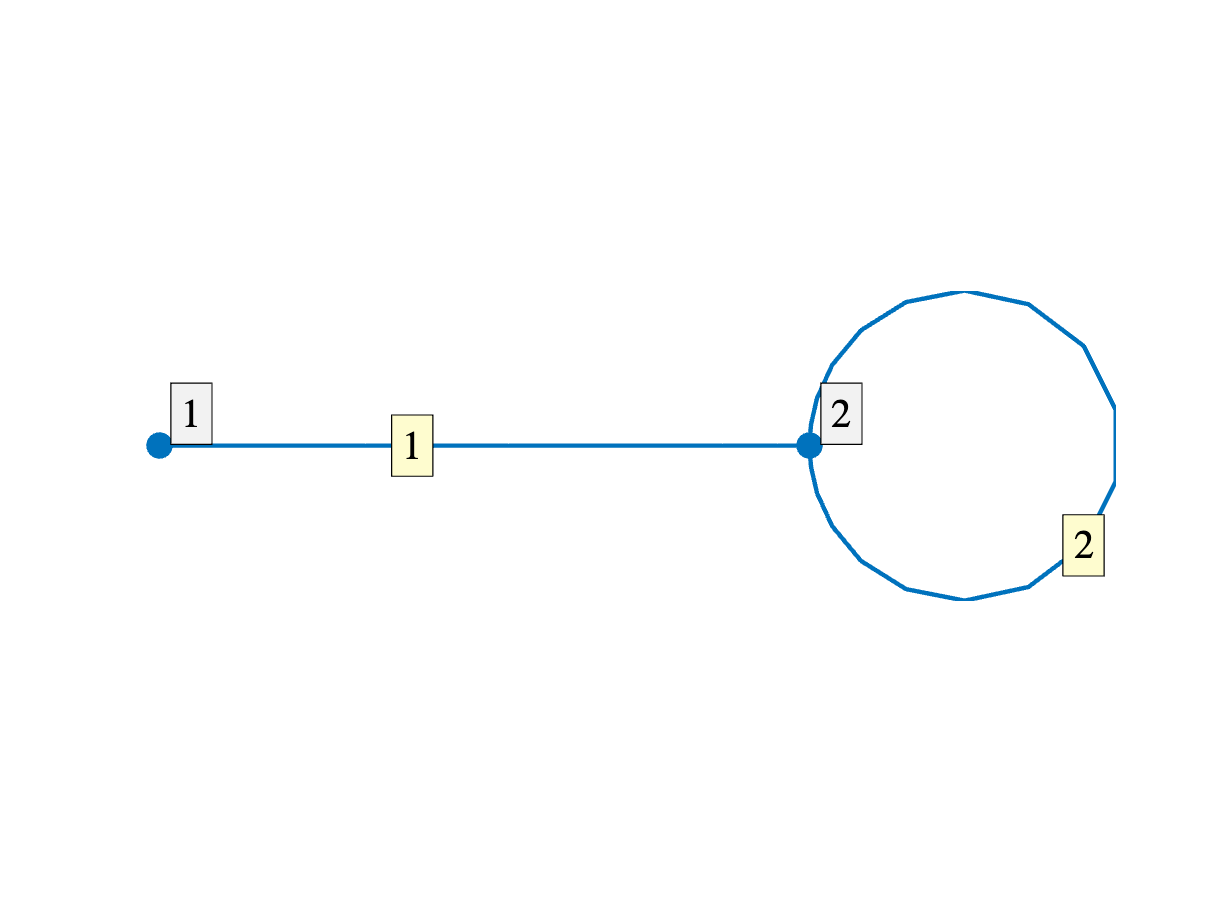

Phi1 = quantumGraphFromTemplate('multibell',nBells=1,LVec=[2;L2(1)],discretization='Chebyshev');
Phi1.plot('layout')

#### Calculate the eigenvalues for changing $L$

for k=1:numLengths+1
    LL = [2;L2(k)];
    Phi1 = quantumGraphFromTemplate('multibell',nBells=1,LVec=LL,discretization='Chebyshev',nx=[32; 128]);
    [V1,d1]=Phi1.eigs(numEigs);
    eigMatrix(:,k)=d1;
end

#### Plot the Eigenvalues

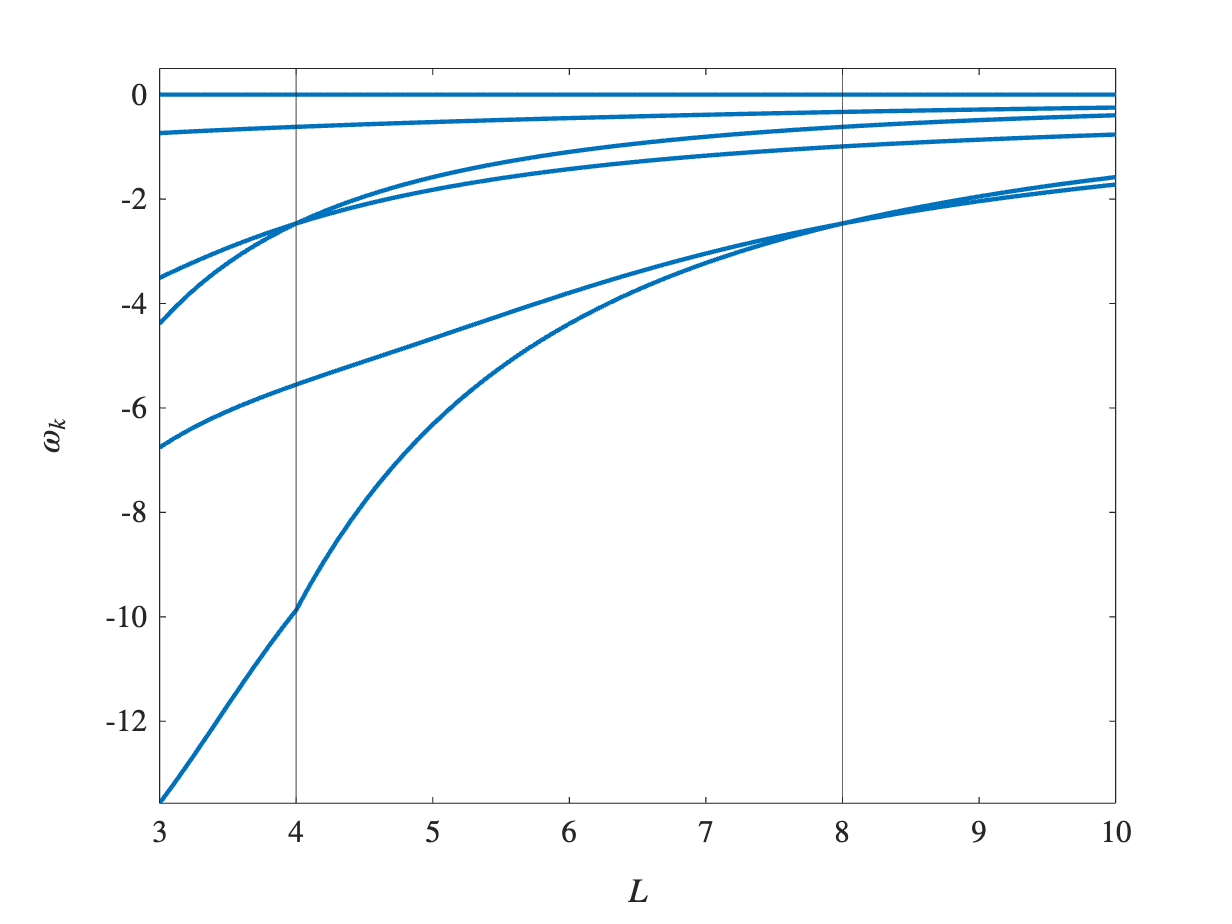

plot(L2,eigMatrix,'color',mcolor('b'))
xlabel('$L$')
ylabel('$\omega_k$')
xline(4)
xline(8)
axis([Lmin Lmax min(eigMatrix(:)) 0.5])

At $L=4$ and $L=8$, marked by vertical lines, there is a resonance between the lengths of the two segments, leading to a multiplicity-two eigenvalue, so two of the curves are tangent.